clc
clear

dotQ=[1;1;1;1;1;1];
ke=100;
kp=10;
%initial value
Q=[0;0;0;0;0;0];
Qa=[0;0;0;0;0;0];
q=[0;0;0;0;0;0];
Qy=40;
%dt
elasticdt=0.005;
plasticdt=0.005/100;

if norm(Q(:,1))-Qy>0
else
    iflag=0;
end

for i=1:40000
    if iflag==0
        q(:,i+1)=q(:,i)+(dotQ/ke)*elasticdt;
        Q(:,i+1)=Q(:,i)+dotQ*elasticdt;
        Qa(:,i+1)=Qa(:,i)+dotQ*elasticdt;
        if norm(Q(:,i+1))-Qy>0
            if Q(:,i+1)'*dotQ<0
                iflag=0;
                q(:,i+1)=q(:,i)+(dotQ/ke)*elasticdt;
                Q(:,i+1)=Q(:,i)+dotQ*elasticdt;
                Qa(:,i+1)=Qa(:,i)+dotQ*elasticdt;
            else
                iflag=1;
                i
                syms dt
                f=Q(:,i)+dotQ*dt;
                f1=norm(f)-Qy;
                dt1=solve(f1,dt);
                dt=double(dt1);
                aa=find (dt<0);
                dt(aa)=[];
                q(:,i+1)=q(:,i)+(dotQ/ke)*dt;
                Q(:,i+1)=Q(:,i)+dotQ*dt;%Qton
                Qa(:,i+1)=Qa(:,i)+dotQ*dt;
                ik=1;
            end
        end
    end
    if iflag==1 && ik==0
        q(:,i+1)=q(:,i)+(Qa(:,i)'*dotQ*Qa(:,i)/(kp*Qy*Qy)+dotQ/ke)*plasticdt;
        Q(:,i+1)=Q(:,i)+dotQ*plasticdt;
        Qa(:,i+1)=Qa(:,i)+(-Qa(:,i)'*dotQ*Qa(:,i)/(Qy*Qy)+dotQ)*plasticdt;
        if Q(:,i+1)'*dotQ<0
            iflag=0;
            q(:,i+1)=q(:,i)+(dotQ/ke)*elasticdt;
            Q(:,i+1)=Q(:,i)+dotQ*elasticdt;
            Qa(:,i+1)=Qa(:,i)+dotQ*elasticdt;
        end
    end
    ik=0;
end

i = 3266

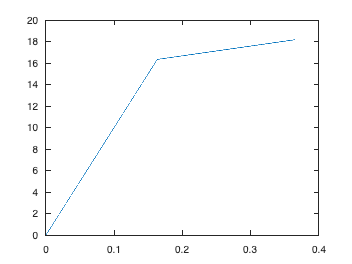

plot(q(1,:),Q(1,:))

for i=1:size(Q,2)
    norm(Qa(:,i))-Qy
end

ans = -40

ans = -39.9878

ans = -39.9755

ans = -39.9633

ans = -39.9510

ans = -39.9388

ans = -39.9265

ans = -39.9143

ans = -39.9020

ans = -39.8898

ans = -39.8775

ans = -39.8653

ans = -39.8530

ans = -39.8408

ans = -39.8285

ans = -39.8163

ans = -39.8040

ans = -39.7918

ans = -39.7795

ans = -39.7673

ans = -39.7551

ans = -39.7428

ans = -39.7306

ans = -39.7183

ans = -39.7061

ans = -39.6938

ans = -39.6816

ans = -39.6693

ans = -39.6571

ans = -39.6448

ans = -39.6326

ans = -39.6203

ans = -39.6081

ans = -39.5958

ans = -39.5836

ans = -39.5713

ans = -39.5591

ans = -39.5468

ans = -39.5346

ans = -39.5223

ans = -39.5101

ans = -39.4979

ans = -39.4856

ans = -39.4734

ans = -39.4611

ans = -39.4489

ans = -39.4366

ans = -39.4244

ans = -39.4121

ans = -39.3999

ans = -39.3876

ans = -39.3754

ans = -39.3631

ans = -39.3509

ans = -39.3386

ans = -39.3264

ans = -39.3141

ans = -39.3019

ans = -39.2896

ans = -39.2774

ans = -39.2652

ans = -39.2529

ans = -39.2407

ans = -39.2284

ans = -39.2162

ans = -39.2039

ans = -39.1917

ans = -39.1794

ans = -39.1672

ans = -39.1549

ans = -39.1427

ans = -39.1304

ans = -39.1182

ans = -39.1059

ans = -39.0937

ans = -39.0814

ans = -39.0692

ans = -39.0569

ans = -39.0447

ans = -39.0325

ans = -39.0202

ans = -39.0080

ans = -38.9957

ans = -38.9835

ans = -38.9712

ans = -38.9590

ans = -38.9467

ans = -38.9345

ans = -38.9222

ans = -38.9100

ans = -38.8977

ans = -38.8855

ans = -38.8732

ans = -38.8610

ans = -38.8487

ans = -38.8365

ans = -38.8242

ans = -38.8120

ans = -38.7998

ans = -38.7875

ans = -38.7753

ans = -38.7630

ans = -38.7508

ans = -38.7385

ans = -38.7263

ans = -38.7140

ans = -38.7018

ans = -38.6895

ans = -38.6773

ans = -38.6650

ans = -38.6528

ans = -38.6405

ans = -38.6283

ans = -38.6160

ans = -38.6038

ans = -38.5915

ans = -38.5793

ans = -38.5670

ans = -38.5548

ans = -38.5426

ans = -38.5303

ans = -38.5181

ans = -38.5058

ans = -38.4936

ans = -38.4813

ans = -38.4691

ans = -38.4568

ans = -38.4446

ans = -38.4323

ans = -38.4201

ans = -38.4078

ans = -38.3956

ans = -38.3833

ans = -38.3711

ans = -38.3588

ans = -38.3466

ans = -38.3343

ans = -38.3221

ans = -38.3099

ans = -38.2976

ans = -38.2854

ans = -38.2731

ans = -38.2609

ans = -38.2486

ans = -38.2364

ans = -38.2241

ans = -38.2119

ans = -38.1996

ans = -38.1874

ans = -38.1751

ans = -38.1629

ans = -38.1506

ans = -38.1384

ans = -38.1261

ans = -38.1139

ans = -38.1016

ans = -38.0894

ans = -38.0772

ans = -38.0649

ans = -38.0527

ans = -38.0404

ans = -38.0282

ans = -38.0159

ans = -38.0037

ans = -37.9914

ans = -37.9792

ans = -37.9669

ans = -37.9547

ans = -37.9424

ans = -37.9302

ans = -37.9179

ans = -37.9057

ans = -37.8934

ans = -37.8812

ans = -37.8689

ans = -37.8567

ans = -37.8444

ans = -37.8322

ans = -37.8200

ans = -37.8077

ans = -37.7955

ans = -37.7832

ans = -37.7710

ans = -37.7587

ans = -37.7465

ans = -37.7342

ans = -37.7220

ans = -37.7097

ans = -37.6975

ans = -37.6852

ans = -37.6730

ans = -37.6607

ans = -37.6485

ans = -37.6362

ans = -37.6240

ans = -37.6117

ans = -37.5995

ans = -37.5873

ans = -37.5750

ans = -37.5628

ans = -37.5505

ans = -37.5383

ans = -37.5260

ans = -37.5138

ans = -37.5015

ans = -37.4893

ans = -37.4770

ans = -37.4648

ans = -37.4525

ans = -37.4403

ans = -37.4280

ans = -37.4158

ans = -37.4035

ans = -37.3913

ans = -37.3790

ans = -37.3668

ans = -37.3546

ans = -37.3423

ans = -37.3301

ans = -37.3178

ans = -37.3056

ans = -37.2933

ans = -37.2811

ans = -37.2688

ans = -37.2566

ans = -37.2443

ans = -37.2321

ans = -37.2198

ans = -37.2076

ans = -37.1953

ans = -37.1831

ans = -37.1708

ans = -37.1586

ans = -37.1463

ans = -37.1341

ans = -37.1218

ans = -37.1096

ans = -37.0974

ans = -37.0851

ans = -37.0729

ans = -37.0606

ans = -37.0484

ans = -37.0361

ans = -37.0239

ans = -37.0116

ans = -36.9994

ans = -36.9871

ans = -36.9749

ans = -36.9626

ans = -36.9504

ans = -36.9381

ans = -36.9259

ans = -36.9136

ans = -36.9014

ans = -36.8891

ans = -36.8769

ans = -36.8647

ans = -36.8524

ans = -36.8402

ans = -36.8279

ans = -36.8157

ans = -36.8034

ans = -36.7912

ans = -36.7789

ans = -36.7667

ans = -36.7544

ans = -36.7422

ans = -36.7299

ans = -36.7177

ans = -36.7054

ans = -36.6932

ans = -36.6809

ans = -36.6687

ans = -36.6564

ans = -36.6442

ans = -36.6320

ans = -36.6197

ans = -36.6075

ans = -36.5952

ans = -36.5830

ans = -36.5707

ans = -36.5585

ans = -36.5462

ans = -36.5340

ans = -36.5217

ans = -36.5095

ans = -36.4972

ans = -36.4850

ans = -36.4727

ans = -36.4605

ans = -36.4482

ans = -36.4360

ans = -36.4237

ans = -36.4115

ans = -36.3993

ans = -36.3870

ans = -36.3748

ans = -36.3625

ans = -36.3503

ans = -36.3380

ans = -36.3258

ans = -36.3135

ans = -36.3013

ans = -36.2890

ans = -36.2768

ans = -36.2645

ans = -36.2523

ans = -36.2400

ans = -36.2278

ans = -36.2155

ans = -36.2033

ans = -36.1910

ans = -36.1788

ans = -36.1665

ans = -36.1543

ans = -36.1421

ans = -36.1298

ans = -36.1176

ans = -36.1053

ans = -36.0931

ans = -36.0808

ans = -36.0686

ans = -36.0563

ans = -36.0441

ans = -36.0318

ans = -36.0196

ans = -36.0073

ans = -35.9951

ans = -35.9828

ans = -35.9706

ans = -35.9583

ans = -35.9461

ans = -35.9338

ans = -35.9216

ans = -35.9094

ans = -35.8971

ans = -35.8849

ans = -35.8726

ans = -35.8604

ans = -35.8481

ans = -35.8359

ans = -35.8236

ans = -35.8114

ans = -35.7991

ans = -35.7869

ans = -35.7746

ans = -35.7624

ans = -35.7501

ans = -35.7379

ans = -35.7256

ans = -35.7134

ans = -35.7011

ans = -35.6889

ans = -35.6767

ans = -35.6644

ans = -35.6522

ans = -35.6399

ans = -35.6277

ans = -35.6154

ans = -35.6032

ans = -35.5909

ans = -35.5787

ans = -35.5664

ans = -35.5542

ans = -35.5419

ans = -35.5297

ans = -35.5174

ans = -35.5052

ans = -35.4929

ans = -35.4807

ans = -35.4684

ans = -35.4562

ans = -35.4439

ans = -35.4317

ans = -35.4195

ans = -35.4072

ans = -35.3950

ans = -35.3827

ans = -35.3705

ans = -35.3582

ans = -35.3460

ans = -35.3337

ans = -35.3215

ans = -35.3092

ans = -35.2970

ans = -35.2847

ans = -35.2725

ans = -35.2602

ans = -35.2480

ans = -35.2357

ans = -35.2235

ans = -35.2112

ans = -35.1990

ans = -35.1868

ans = -35.1745

ans = -35.1623

ans = -35.1500

ans = -35.1378

ans = -35.1255

ans = -35.1133

ans = -35.1010

ans = -35.0888

ans = -35.0765

ans = -35.0643

ans = -35.0520

ans = -35.0398

ans = -35.0275

ans = -35.0153

ans = -35.0030

ans = -34.9908

ans = -34.9785

ans = -34.9663

ans = -34.9541

ans = -34.9418

ans = -34.9296

ans = -34.9173

ans = -34.9051

ans = -34.8928

ans = -34.8806

ans = -34.8683

ans = -34.8561

ans = -34.8438

ans = -34.8316

ans = -34.8193

ans = -34.8071

ans = -34.7948

ans = -34.7826

ans = -34.7703

ans = -34.7581

ans = -34.7458

ans = -34.7336

ans = -34.7213

ans = -34.7091

ans = -34.6969

ans = -34.6846

ans = -34.6724

ans = -34.6601

ans = -34.6479

ans = -34.6356

ans = -34.6234

ans = -34.6111

ans = -34.5989

ans = -34.5866

ans = -34.5744

ans = -34.5621

ans = -34.5499

ans = -34.5376

ans = -34.5254

ans = -34.5131

ans = -34.5009

ans = -34.4886

ans = -34.4764

ans = -34.4642

ans = -34.4519

ans = -34.4397

ans = -34.4274

ans = -34.4152

ans = -34.4029

ans = -34.3907

ans = -34.3784

ans = -34.3662

ans = -34.3539

ans = -34.3417

ans = -34.3294

ans = -34.3172

ans = -34.3049

ans = -34.2927

ans = -34.2804

ans = -34.2682

ans = -34.2559

ans = -34.2437

ans = -34.2315

ans = -34.2192

ans = -34.2070

ans = -34.1947

ans = -34.1825

ans = -34.1702

ans = -34.1580

ans = -34.1457

ans = -34.1335

ans = -34.1212

ans = -34.1090

ans = -34.0967

ans = -34.0845

ans = -34.0722

ans = -34.0600

ans = -34.0477

ans = -34.0355

ans = -34.0232

ans = -34.0110

ans = -33.9988

ans = -33.9865

ans = -33.9743

ans = -33.9620

ans = -33.9498

ans = -33.9375

ans = -33.9253

ans = -33.9130

ans = -33.9008

ans = -33.8885

ans = -33.8763

ans = -33.8640

ans = -33.8518

ans = -33.8395

ans = -33.8273

ans = -33.8150

ans = -33.8028

ans = -33.7905

ans = -33.7783

ans = -33.7660

ans = -33.7538

ans = -33.7416

ans = -33.7293

ans = -33.7171

ans = -33.7048

ans = -33.6926

ans = -33.6803

ans = -33.6681

ans = -33.6558

ans = -33.6436

ans = -33.6313

ans = -33.6191

ans = -33.6068

ans = -33.5946

ans = -33.5823

ans = -33.5701

ans = -33.5578

ans = -33.5456

ans = -33.5333

ans = -33.5211

ans = -33.5089

ans = -33.4966

ans = -33.4844

ans = -33.4721

ans = -33.4599

ans = -33.4476

ans = -33.4354

ans = -33.4231

ans = -33.4109

ans = -33.3986

ans = -33.3864

ans = -33.3741

ans = -33.3619

ans = -33.3496

ans = -33.3374

ans = -33.3251

ans = -33.3129

ans = -33.3006

ans = -33.2884

ans = -33.2762

ans = -33.2639

ans = -33.2517

ans = -33.2394

ans = -33.2272

ans = -33.2149

ans = -33.2027

ans = -33.1904

ans = -33.1782

ans = -33.1659

ans = -33.1537

ans = -33.1414

ans = -33.1292

ans = -33.1169

ans = -33.1047

ans = -33.0924

ans = -33.0802

ans = -33.0679

ans = -33.0557

ans = -33.0434

ans = -33.0312

ans = -33.0190

ans = -33.0067

ans = -32.9945

ans = -32.9822

ans = -32.9700

ans = -32.9577

ans = -32.9455

ans = -32.9332

ans = -32.9210

ans = -32.9087

ans = -32.8965

ans = -32.8842

ans = -32.8720

ans = -32.8597

ans = -32.8475

ans = -32.8352

ans = -32.8230

ans = -32.8107

ans = -32.7985

ans = -32.7863

ans = -32.7740

ans = -32.7618

ans = -32.7495

ans = -32.7373

ans = -32.7250

ans = -32.7128

ans = -32.7005

ans = -32.6883

ans = -32.6760

ans = -32.6638

ans = -32.6515

ans = -32.6393

ans = -32.6270

ans = -32.6148

ans = -32.6025

ans = -32.5903

ans = -32.5780

ans = -32.5658

ans = -32.5536

ans = -32.5413

ans = -32.5291

ans = -32.5168

ans = -32.5046

ans = -32.4923

ans = -32.4801

ans = -32.4678

ans = -32.4556

ans = -32.4433

ans = -32.4311

ans = -32.4188

ans = -32.4066

ans = -32.3943

ans = -32.3821

ans = -32.3698

ans = -32.3576

ans = -32.3453

ans = -32.3331

ans = -32.3208

ans = -32.3086

ans = -32.2964

ans = -32.2841

ans = -32.2719

ans = -32.2596

ans = -32.2474

ans = -32.2351

ans = -32.2229

ans = -32.2106

ans = -32.1984

ans = -32.1861

ans = -32.1739

ans = -32.1616

ans = -32.1494

ans = -32.1371

ans = -32.1249

ans = -32.1126

ans = -32.1004

ans = -32.0881

ans = -32.0759

ans = -32.0637

ans = -32.0514

ans = -32.0392

ans = -32.0269

ans = -32.0147

ans = -32.0024

ans = -31.9902

ans = -31.9779

ans = -31.9657

ans = -31.9534

ans = -31.9412

ans = -31.9289

ans = -31.9167

ans = -31.9044

ans = -31.8922

ans = -31.8799

ans = -31.8677

ans = -31.8554

ans = -31.8432

ans = -31.8310

ans = -31.8187

ans = -31.8065

ans = -31.7942

ans = -31.7820

ans = -31.7697

ans = -31.7575

ans = -31.7452

ans = -31.7330

ans = -31.7207

ans = -31.7085

ans = -31.6962

ans = -31.6840

ans = -31.6717

ans = -31.6595

ans = -31.6472

ans = -31.6350

ans = -31.6227

ans = -31.6105

ans = -31.5983

ans = -31.5860

ans = -31.5738

ans = -31.5615

ans = -31.5493

ans = -31.5370

ans = -31.5248

ans = -31.5125

ans = -31.5003

ans = -31.4880

ans = -31.4758

ans = -31.4635

ans = -31.4513

ans = -31.4390

ans = -31.4268

ans = -31.4145

ans = -31.4023

ans = -31.3900

ans = -31.3778

ans = -31.3655

ans = -31.3533

ans = -31.3411

ans = -31.3288

ans = -31.3166

ans = -31.3043

ans = -31.2921

ans = -31.2798

ans = -31.2676

ans = -31.2553

ans = -31.2431

ans = -31.2308

ans = -31.2186

ans = -31.2063

ans = -31.1941

ans = -31.1818

ans = -31.1696

ans = -31.1573

ans = -31.1451

ans = -31.1328

ans = -31.1206

ans = -31.1084

ans = -31.0961

ans = -31.0839

ans = -31.0716

ans = -31.0594

ans = -31.0471

ans = -31.0349

ans = -31.0226

ans = -31.0104

ans = -30.9981

ans = -30.9859

ans = -30.9736

ans = -30.9614

ans = -30.9491

ans = -30.9369

ans = -30.9246

ans = -30.9124

ans = -30.9001

ans = -30.8879

ans = -30.8757

ans = -30.8634

ans = -30.8512

ans = -30.8389

ans = -30.8267

ans = -30.8144

ans = -30.8022

ans = -30.7899

ans = -30.7777

ans = -30.7654

ans = -30.7532

ans = -30.7409

ans = -30.7287

ans = -30.7164

ans = -30.7042

ans = -30.6919

ans = -30.6797

ans = -30.6674

ans = -30.6552

ans = -30.6429

ans = -30.6307

ans = -30.6185

ans = -30.6062

ans = -30.5940

ans = -30.5817

ans = -30.5695

ans = -30.5572

ans = -30.5450

ans = -30.5327

ans = -30.5205

ans = -30.5082

ans = -30.4960

ans = -30.4837

ans = -30.4715

ans = -30.4592

ans = -30.4470

ans = -30.4347

ans = -30.4225

ans = -30.4102

ans = -30.3980

ans = -30.3858

ans = -30.3735

ans = -30.3613

ans = -30.3490

ans = -30.3368

ans = -30.3245

ans = -30.3123

ans = -30.3000

ans = -30.2878

ans = -30.2755

ans = -30.2633

ans = -30.2510

ans = -30.2388

ans = -30.2265

ans = -30.2143

ans = -30.2020

ans = -30.1898

ans = -30.1775

ans = -30.1653

ans = -30.1531

ans = -30.1408

ans = -30.1286

ans = -30.1163

ans = -30.1041

ans = -30.0918

ans = -30.0796

ans = -30.0673

ans = -30.0551

ans = -30.0428

ans = -30.0306

ans = -30.0183

ans = -30.0061

ans = -29.9938

ans = -29.9816

ans = -29.9693

ans = -29.9571

ans = -29.9448

ans = -29.9326

ans = -29.9203

ans = -29.9081

ans = -29.8959

ans = -29.8836

ans = -29.8714

ans = -29.8591

ans = -29.8469

ans = -29.8346

ans = -29.8224

ans = -29.8101

ans = -29.7979

ans = -29.7856

ans = -29.7734

ans = -29.7611

ans = -29.7489

ans = -29.7366

ans = -29.7244

ans = -29.7121

ans = -29.6999

ans = -29.6876

ans = -29.6754

ans = -29.6632

ans = -29.6509

ans = -29.6387

ans = -29.6264

ans = -29.6142

ans = -29.6019

ans = -29.5897

ans = -29.5774

ans = -29.5652

ans = -29.5529

ans = -29.5407

ans = -29.5284

ans = -29.5162

ans = -29.5039

ans = -29.4917

ans = -29.4794

ans = -29.4672

ans = -29.4549

ans = -29.4427

ans = -29.4305

ans = -29.4182

ans = -29.4060

ans = -29.3937

ans = -29.3815

ans = -29.3692

ans = -29.3570

ans = -29.3447

ans = -29.3325

ans = -29.3202

ans = -29.3080

ans = -29.2957

ans = -29.2835

ans = -29.2712

ans = -29.2590

ans = -29.2467

ans = -29.2345

ans = -29.2222

ans = -29.2100

ans = -29.1978

ans = -29.1855

ans = -29.1733

ans = -29.1610

ans = -29.1488

ans = -29.1365

ans = -29.1243

ans = -29.1120

ans = -29.0998

ans = -29.0875

ans = -29.0753

ans = -29.0630

ans = -29.0508

ans = -29.0385

ans = -29.0263

ans = -29.0140

ans = -29.0018

ans = -28.9895

ans = -28.9773

ans = -28.9650

ans = -28.9528

ans = -28.9406

ans = -28.9283

ans = -28.9161

ans = -28.9038

ans = -28.8916

ans = -28.8793

ans = -28.8671

ans = -28.8548

ans = -28.8426

ans = -28.8303

ans = -28.8181

ans = -28.8058

ans = -28.7936

ans = -28.7813

ans = -28.7691

ans = -28.7568

ans = -28.7446

ans = -28.7323

ans = -28.7201

ans = -28.7079

ans = -28.6956

ans = -28.6834

ans = -28.6711

ans = -28.6589

ans = -28.6466

ans = -28.6344

ans = -28.6221

ans = -28.6099

ans = -28.5976

ans = -28.5854

ans = -28.5731

ans = -28.5609

ans = -28.5486

ans = -28.5364

ans = -28.5241

ans = -28.5119

ans = -28.4996

ans = -28.4874

ans = -28.4752

ans = -28.4629

ans = -28.4507

ans = -28.4384

ans = -28.4262

ans = -28.4139

ans = -28.4017

ans = -28.3894

ans = -28.3772

ans = -28.3649

ans = -28.3527

ans = -28.3404

ans = -28.3282

ans = -28.3159

ans = -28.3037

ans = -28.2914

ans = -28.2792

ans = -28.2669

ans = -28.2547

ans = -28.2424

ans = -28.2302

ans = -28.2180

ans = -28.2057

ans = -28.1935

ans = -28.1812

ans = -28.1690

ans = -28.1567

ans = -28.1445

ans = -28.1322

ans = -28.1200

ans = -28.1077

ans = -28.0955

ans = -28.0832

ans = -28.0710

ans = -28.0587

ans = -28.0465

ans = -28.0342

ans = -28.0220

ans = -28.0097

ans = -27.9975

ans = -27.9853

ans = -27.9730

ans = -27.9608

ans = -27.9485

ans = -27.9363

ans = -27.9240

ans = -27.9118

ans = -27.8995

ans = -27.8873

ans = -27.8750

ans = -27.8628

ans = -27.8505

ans = -27.8383

ans = -27.8260

ans = -27.8138

ans = -27.8015

ans = -27.7893

ans = -27.7770

ans = -27.7648

ans = -27.7526

ans = -27.7403

ans = -27.7281

ans = -27.7158

ans = -27.7036

ans = -27.6913

ans = -27.6791

ans = -27.6668

ans = -27.6546

ans = -27.6423

ans = -27.6301

ans = -27.6178

ans = -27.6056

ans = -27.5933

ans = -27.5811

ans = -27.5688

ans = -27.5566

ans = -27.5443

ans = -27.5321

ans = -27.5198

ans = -27.5076

ans = -27.4954

ans = -27.4831

ans = -27.4709

ans = -27.4586

ans = -27.4464

ans = -27.4341

ans = -27.4219

ans = -27.4096

ans = -27.3974

ans = -27.3851

ans = -27.3729

ans = -27.3606

ans = -27.3484

ans = -27.3361

ans = -27.3239

ans = -27.3116

ans = -27.2994

ans = -27.2871

ans = -27.2749

ans = -27.2627

ans = -27.2504

ans = -27.2382

ans = -27.2259

ans = -27.2137

ans = -27.2014

ans = -27.1892

ans = -27.1769

ans = -27.1647

ans = -27.1524

ans = -27.1402

ans = -27.1279

ans = -27.1157

ans = -27.1034

ans = -27.0912

ans = -27.0789

ans = -27.0667

ans = -27.0544

ans = -27.0422

ans = -27.0300

ans = -27.0177

ans = -27.0055

ans = -26.9932

ans = -26.9810

ans = -26.9687

ans = -26.9565

ans = -26.9442

ans = -26.9320

ans = -26.9197

ans = -26.9075

ans = -26.8952

ans = -26.8830

ans = -26.8707

ans = -26.8585

ans = -26.8462

ans = -26.8340

ans = -26.8217

ans = -26.8095

ans = -26.7973

ans = -26.7850

ans = -26.7728

ans = -26.7605

ans = -26.7483

ans = -26.7360

ans = -26.7238

ans = -26.7115

ans = -26.6993

ans = -26.6870

ans = -26.6748

ans = -26.6625

ans = -26.6503

ans = -26.6380

ans = -26.6258

ans = -26.6135

ans = -26.6013

ans = -26.5890

ans = -26.5768

ans = -26.5645

ans = -26.5523

ans = -26.5401

ans = -26.5278

ans = -26.5156

ans = -26.5033

ans = -26.4911

ans = -26.4788

ans = -26.4666

ans = -26.4543

ans = -26.4421

ans = -26.4298

ans = -26.4176

ans = -26.4053

ans = -26.3931

ans = -26.3808

ans = -26.3686

ans = -26.3563

ans = -26.3441

ans = -26.3318

ans = -26.3196

ans = -26.3074

ans = -26.2951

ans = -26.2829

ans = -26.2706

ans = -26.2584

ans = -26.2461

ans = -26.2339

ans = -26.2216

ans = -26.2094

ans = -26.1971

ans = -26.1849

ans = -26.1726

ans = -26.1604

ans = -26.1481

ans = -26.1359

ans = -26.1236

ans = -26.1114

ans = -26.0991

ans = -26.0869

ans = -26.0747

ans = -26.0624

ans = -26.0502

ans = -26.0379

ans = -26.0257

ans = -26.0134

ans = -26.0012

ans = -25.9889

ans = -25.9767

ans = -25.9644

ans = -25.9522

ans = -25.9399

ans = -25.9277

ans = -25.9154

ans = -25.9032

ans = -25.8909

ans = -25.8787

ans = -25.8664

ans = -25.8542

ans = -25.8419

ans = -25.8297

ans = -25.8175

ans = -25.8052

ans = -25.7930

ans = -25.7807

ans = -25.7685

ans = -25.7562

ans = -25.7440

ans = -25.7317

ans = -25.7195

ans = -25.7072

ans = -25.6950

ans = -25.6827

ans = -25.6705

ans = -25.6582

ans = -25.6460

ans = -25.6337

ans = -25.6215

ans = -25.6092

ans = -25.5970

ans = -25.5848

ans = -25.5725

ans = -25.5603

ans = -25.5480

ans = -25.5358

ans = -25.5235

ans = -25.5113

ans = -25.4990

ans = -25.4868

ans = -25.4745

ans = -25.4623

ans = -25.4500

ans = -25.4378

ans = -25.4255

ans = -25.4133

ans = -25.4010

ans = -25.3888

ans = -25.3765

ans = -25.3643

ans = -25.3521

ans = -25.3398

ans = -25.3276

ans = -25.3153

ans = -25.3031

ans = -25.2908

ans = -25.2786

ans = -25.2663

ans = -25.2541

ans = -25.2418

ans = -25.2296

ans = -25.2173

ans = -25.2051

ans = -25.1928

ans = -25.1806

ans = -25.1683

ans = -25.1561

ans = -25.1438

ans = -25.1316

ans = -25.1193

ans = -25.1071

ans = -25.0949

ans = -25.0826

ans = -25.0704

ans = -25.0581

ans = -25.0459

ans = -25.0336

ans = -25.0214

ans = -25.0091

ans = -24.9969

ans = -24.9846

ans = -24.9724

ans = -24.9601

ans = -24.9479

ans = -24.9356

ans = -24.9234

ans = -24.9111

ans = -24.8989

ans = -24.8866

ans = -24.8744

ans = -24.8622

ans = -24.8499

ans = -24.8377

ans = -24.8254

ans = -24.8132

ans = -24.8009

ans = -24.7887

ans = -24.7764

ans = -24.7642

ans = -24.7519

ans = -24.7397

ans = -24.7274

ans = -24.7152

ans = -24.7029

ans = -24.6907

ans = -24.6784

ans = -24.6662

ans = -24.6539

ans = -24.6417

ans = -24.6295

ans = -24.6172

ans = -24.6050

ans = -24.5927

ans = -24.5805

ans = -24.5682

ans = -24.5560

ans = -24.5437

ans = -24.5315

ans = -24.5192

ans = -24.5070

ans = -24.4947

ans = -24.4825

ans = -24.4702

ans = -24.4580

ans = -24.4457

ans = -24.4335

ans = -24.4212

ans = -24.4090

ans = -24.3968

ans = -24.3845

ans = -24.3723

ans = -24.3600

ans = -24.3478

ans = -24.3355

ans = -24.3233

ans = -24.3110

ans = -24.2988

ans = -24.2865

ans = -24.2743

ans = -24.2620

ans = -24.2498

ans = -24.2375

ans = -24.2253

ans = -24.2130

ans = -24.2008

ans = -24.1885

ans = -24.1763

ans = -24.1640

ans = -24.1518

ans = -24.1396

ans = -24.1273

ans = -24.1151

ans = -24.1028

ans = -24.0906

ans = -24.0783

ans = -24.0661

ans = -24.0538

ans = -24.0416

ans = -24.0293

ans = -24.0171

ans = -24.0048

ans = -23.9926

ans = -23.9803

ans = -23.9681

ans = -23.9558

ans = -23.9436

ans = -23.9313

ans = -23.9191

ans = -23.9069

ans = -23.8946

ans = -23.8824

ans = -23.8701

ans = -23.8579

ans = -23.8456

ans = -23.8334

ans = -23.8211

ans = -23.8089

ans = -23.7966

ans = -23.7844

ans = -23.7721

ans = -23.7599

ans = -23.7476

ans = -23.7354

ans = -23.7231

ans = -23.7109

ans = -23.6986

ans = -23.6864

ans = -23.6742

ans = -23.6619

ans = -23.6497

ans = -23.6374

ans = -23.6252

ans = -23.6129

ans = -23.6007

ans = -23.5884

ans = -23.5762

ans = -23.5639

ans = -23.5517

ans = -23.5394

ans = -23.5272

ans = -23.5149

ans = -23.5027

ans = -23.4904

ans = -23.4782

ans = -23.4659

ans = -23.4537

ans = -23.4414

ans = -23.4292

ans = -23.4170

ans = -23.4047

ans = -23.3925

ans = -23.3802

ans = -23.3680

ans = -23.3557

ans = -23.3435

ans = -23.3312

ans = -23.3190

ans = -23.3067

ans = -23.2945

ans = -23.2822

ans = -23.2700

ans = -23.2577

ans = -23.2455

ans = -23.2332

ans = -23.2210

ans = -23.2087

ans = -23.1965

ans = -23.1843

ans = -23.1720

ans = -23.1598

ans = -23.1475

ans = -23.1353

ans = -23.1230

ans = -23.1108

ans = -23.0985

ans = -23.0863

ans = -23.0740

ans = -23.0618

ans = -23.0495

ans = -23.0373

ans = -23.0250

ans = -23.0128

ans = -23.0005

ans = -22.9883

ans = -22.9760

ans = -22.9638

ans = -22.9516

ans = -22.9393

ans = -22.9271

ans = -22.9148

ans = -22.9026

ans = -22.8903

ans = -22.8781

ans = -22.8658

ans = -22.8536

ans = -22.8413

ans = -22.8291

ans = -22.8168

ans = -22.8046

ans = -22.7923

ans = -22.7801

ans = -22.7678

ans = -22.7556

ans = -22.7433

ans = -22.7311

ans = -22.7188

ans = -22.7066

ans = -22.6944

ans = -22.6821

ans = -22.6699

ans = -22.6576

ans = -22.6454

ans = -22.6331

ans = -22.6209

ans = -22.6086

ans = -22.5964

ans = -22.5841

ans = -22.5719

ans = -22.5596

ans = -22.5474

ans = -22.5351

ans = -22.5229

ans = -22.5106

ans = -22.4984

ans = -22.4861

ans = -22.4739

ans = -22.4617

ans = -22.4494

ans = -22.4372

ans = -22.4249

ans = -22.4127

ans = -22.4004

ans = -22.3882

ans = -22.3759

ans = -22.3637

ans = -22.3514

ans = -22.3392

ans = -22.3269

ans = -22.3147

ans = -22.3024

ans = -22.2902

ans = -22.2779

ans = -22.2657

ans = -22.2534

ans = -22.2412

ans = -22.2290

ans = -22.2167

ans = -22.2045

ans = -22.1922

ans = -22.1800

ans = -22.1677

ans = -22.1555

ans = -22.1432

ans = -22.1310

ans = -22.1187

ans = -22.1065

ans = -22.0942

ans = -22.0820

ans = -22.0697

ans = -22.0575

ans = -22.0452

ans = -22.0330

ans = -22.0207

ans = -22.0085

ans = -21.9963

ans = -21.9840

ans = -21.9718

ans = -21.9595

ans = -21.9473

ans = -21.9350

ans = -21.9228

ans = -21.9105

ans = -21.8983

ans = -21.8860

ans = -21.8738

ans = -21.8615

ans = -21.8493

ans = -21.8370

ans = -21.8248

ans = -21.8125

ans = -21.8003

ans = -21.7880

ans = -21.7758

ans = -21.7635

ans = -21.7513

ans = -21.7391

ans = -21.7268

ans = -21.7146

ans = -21.7023

ans = -21.6901

ans = -21.6778

ans = -21.6656

ans = -21.6533

ans = -21.6411

ans = -21.6288

ans = -21.6166

ans = -21.6043

ans = -21.5921

ans = -21.5798

ans = -21.5676

ans = -21.5553

ans = -21.5431

ans = -21.5308

ans = -21.5186

ans = -21.5064

ans = -21.4941

ans = -21.4819

ans = -21.4696

ans = -21.4574

ans = -21.4451

ans = -21.4329

ans = -21.4206

ans = -21.4084

ans = -21.3961

ans = -21.3839

ans = -21.3716

ans = -21.3594

ans = -21.3471

ans = -21.3349

ans = -21.3226

ans = -21.3104

ans = -21.2981

ans = -21.2859

ans = -21.2737

ans = -21.2614

ans = -21.2492

ans = -21.2369

ans = -21.2247

ans = -21.2124

ans = -21.2002

ans = -21.1879

ans = -21.1757

ans = -21.1634

ans = -21.1512

ans = -21.1389

ans = -21.1267

ans = -21.1144

ans = -21.1022

ans = -21.0899

ans = -21.0777

ans = -21.0654

ans = -21.0532

ans = -21.0409

ans = -21.0287

ans = -21.0165

ans = -21.0042

ans = -20.9920

ans = -20.9797

ans = -20.9675

ans = -20.9552

ans = -20.9430

ans = -20.9307

ans = -20.9185

ans = -20.9062

ans = -20.8940

ans = -20.8817

ans = -20.8695

ans = -20.8572

ans = -20.8450

ans = -20.8327

ans = -20.8205

ans = -20.8082

ans = -20.7960

ans = -20.7838

ans = -20.7715

ans = -20.7593

ans = -20.7470

ans = -20.7348

ans = -20.7225

ans = -20.7103

ans = -20.6980

ans = -20.6858

ans = -20.6735

ans = -20.6613

ans = -20.6490

ans = -20.6368

ans = -20.6245

ans = -20.6123

ans = -20.6000

ans = -20.5878

ans = -20.5755

ans = -20.5633

ans = -20.5511

ans = -20.5388

ans = -20.5266

ans = -20.5143

ans = -20.5021

ans = -20.4898

ans = -20.4776

ans = -20.4653

ans = -20.4531

ans = -20.4408

ans = -20.4286

ans = -20.4163

ans = -20.4041

ans = -20.3918

ans = -20.3796

ans = -20.3673

ans = -20.3551

ans = -20.3428

ans = -20.3306

ans = -20.3183

ans = -20.3061

ans = -20.2939

ans = -20.2816

ans = -20.2694

ans = -20.2571

ans = -20.2449

ans = -20.2326

ans = -20.2204

ans = -20.2081

ans = -20.1959

ans = -20.1836

ans = -20.1714

ans = -20.1591

ans = -20.1469

ans = -20.1346

ans = -20.1224

ans = -20.1101

ans = -20.0979

ans = -20.0856

ans = -20.0734

ans = -20.0612

ans = -20.0489

ans = -20.0367

ans = -20.0244

ans = -20.0122

ans = -19.9999

ans = -19.9877

ans = -19.9754

ans = -19.9632

ans = -19.9509

ans = -19.9387

ans = -19.9264

ans = -19.9142

ans = -19.9019

ans = -19.8897

ans = -19.8774

ans = -19.8652

ans = -19.8529

ans = -19.8407

ans = -19.8285

ans = -19.8162

ans = -19.8040

ans = -19.7917

ans = -19.7795

ans = -19.7672

ans = -19.7550

ans = -19.7427

ans = -19.7305

ans = -19.7182

ans = -19.7060

ans = -19.6937

ans = -19.6815

ans = -19.6692

ans = -19.6570

ans = -19.6447

ans = -19.6325

ans = -19.6202

ans = -19.6080

ans = -19.5958

ans = -19.5835

ans = -19.5713

ans = -19.5590

ans = -19.5468

ans = -19.5345

ans = -19.5223

ans = -19.5100

ans = -19.4978

ans = -19.4855

ans = -19.4733

ans = -19.4610

ans = -19.4488

ans = -19.4365

ans = -19.4243

ans = -19.4120

ans = -19.3998

ans = -19.3875

ans = -19.3753

ans = -19.3630

ans = -19.3508

ans = -19.3386

ans = -19.3263

ans = -19.3141

ans = -19.3018

ans = -19.2896

ans = -19.2773

ans = -19.2651

ans = -19.2528

ans = -19.2406

ans = -19.2283

ans = -19.2161

ans = -19.2038

ans = -19.1916

ans = -19.1793

ans = -19.1671

ans = -19.1548

ans = -19.1426

ans = -19.1303

ans = -19.1181

ans = -19.1059

ans = -19.0936

ans = -19.0814

ans = -19.0691

ans = -19.0569

ans = -19.0446

ans = -19.0324

ans = -19.0201

ans = -19.0079

ans = -18.9956

ans = -18.9834

ans = -18.9711

ans = -18.9589

ans = -18.9466

ans = -18.9344

ans = -18.9221

ans = -18.9099

ans = -18.8976

ans = -18.8854

ans = -18.8732

ans = -18.8609

ans = -18.8487

ans = -18.8364

ans = -18.8242

ans = -18.8119

ans = -18.7997

ans = -18.7874

ans = -18.7752

ans = -18.7629

ans = -18.7507

ans = -18.7384

ans = -18.7262

ans = -18.7139

ans = -18.7017

ans = -18.6894

ans = -18.6772

ans = -18.6649

ans = -18.6527

ans = -18.6404

ans = -18.6282

ans = -18.6160

ans = -18.6037

ans = -18.5915

ans = -18.5792

ans = -18.5670

ans = -18.5547

ans = -18.5425

ans = -18.5302

ans = -18.5180

ans = -18.5057

ans = -18.4935

ans = -18.4812

ans = -18.4690

ans = -18.4567

ans = -18.4445

ans = -18.4322

ans = -18.4200

ans = -18.4077

ans = -18.3955

ans = -18.3833

ans = -18.3710

ans = -18.3588

ans = -18.3465

ans = -18.3343

ans = -18.3220

ans = -18.3098

ans = -18.2975

ans = -18.2853

ans = -18.2730

ans = -18.2608

ans = -18.2485

ans = -18.2363

ans = -18.2240

ans = -18.2118

ans = -18.1995

ans = -18.1873

ans = -18.1750

ans = -18.1628

ans = -18.1506

ans = -18.1383

ans = -18.1261

ans = -18.1138

ans = -18.1016

ans = -18.0893

ans = -18.0771

ans = -18.0648

ans = -18.0526

ans = -18.0403

ans = -18.0281

ans = -18.0158

ans = -18.0036

ans = -17.9913

ans = -17.9791

ans = -17.9668

ans = -17.9546

ans = -17.9423

ans = -17.9301

ans = -17.9178

ans = -17.9056

ans = -17.8934

ans = -17.8811

ans = -17.8689

ans = -17.8566

ans = -17.8444

ans = -17.8321

ans = -17.8199

ans = -17.8076

ans = -17.7954

ans = -17.7831

ans = -17.7709

ans = -17.7586

ans = -17.7464

ans = -17.7341

ans = -17.7219

ans = -17.7096

ans = -17.6974

ans = -17.6851

ans = -17.6729

ans = -17.6607

ans = -17.6484

ans = -17.6362

ans = -17.6239

ans = -17.6117

ans = -17.5994

ans = -17.5872

ans = -17.5749

ans = -17.5627

ans = -17.5504

ans = -17.5382

ans = -17.5259

ans = -17.5137

ans = -17.5014

ans = -17.4892

ans = -17.4769

ans = -17.4647

ans = -17.4524

ans = -17.4402

ans = -17.4280

ans = -17.4157

ans = -17.4035

ans = -17.3912

ans = -17.3790

ans = -17.3667

ans = -17.3545

ans = -17.3422

ans = -17.3300

ans = -17.3177

ans = -17.3055

ans = -17.2932

ans = -17.2810

ans = -17.2687

ans = -17.2565

ans = -17.2442

ans = -17.2320

ans = -17.2197

ans = -17.2075

ans = -17.1953

ans = -17.1830

ans = -17.1708

ans = -17.1585

ans = -17.1463

ans = -17.1340

ans = -17.1218

ans = -17.1095

ans = -17.0973

ans = -17.0850

ans = -17.0728

ans = -17.0605

ans = -17.0483

ans = -17.0360

ans = -17.0238

ans = -17.0115

ans = -16.9993

ans = -16.9870

ans = -16.9748

ans = -16.9625

ans = -16.9503

ans = -16.9381

ans = -16.9258

ans = -16.9136

ans = -16.9013

ans = -16.8891

ans = -16.8768

ans = -16.8646

ans = -16.8523

ans = -16.8401

ans = -16.8278

ans = -16.8156

ans = -16.8033

ans = -16.7911

ans = -16.7788

ans = -16.7666

ans = -16.7543

ans = -16.7421

ans = -16.7298

ans = -16.7176

ans = -16.7054

ans = -16.6931

ans = -16.6809

ans = -16.6686

ans = -16.6564

ans = -16.6441

ans = -16.6319

ans = -16.6196

ans = -16.6074

ans = -16.5951

ans = -16.5829

ans = -16.5706

ans = -16.5584

ans = -16.5461

ans = -16.5339

ans = -16.5216

ans = -16.5094

ans = -16.4971

ans = -16.4849

ans = -16.4727

ans = -16.4604

ans = -16.4482

ans = -16.4359

ans = -16.4237

ans = -16.4114

ans = -16.3992

ans = -16.3869

ans = -16.3747

ans = -16.3624

ans = -16.3502

ans = -16.3379

ans = -16.3257

ans = -16.3134

ans = -16.3012

ans = -16.2889

ans = -16.2767

ans = -16.2644

ans = -16.2522

ans = -16.2399

ans = -16.2277

ans = -16.2155

ans = -16.2032

ans = -16.1910

ans = -16.1787

ans = -16.1665

ans = -16.1542

ans = -16.1420

ans = -16.1297

ans = -16.1175

ans = -16.1052

ans = -16.0930

ans = -16.0807

ans = -16.0685

ans = -16.0562

ans = -16.0440

ans = -16.0317

ans = -16.0195

ans = -16.0072

ans = -15.9950

ans = -15.9828

ans = -15.9705

ans = -15.9583

ans = -15.9460

ans = -15.9338

ans = -15.9215

ans = -15.9093

ans = -15.8970

ans = -15.8848

ans = -15.8725

ans = -15.8603

ans = -15.8480

ans = -15.8358

ans = -15.8235

ans = -15.8113

ans = -15.7990

ans = -15.7868

ans = -15.7745

ans = -15.7623

ans = -15.7501

ans = -15.7378

ans = -15.7256

ans = -15.7133

ans = -15.7011

ans = -15.6888

ans = -15.6766

ans = -15.6643

ans = -15.6521

ans = -15.6398

ans = -15.6276

ans = -15.6153

ans = -15.6031

ans = -15.5908

ans = -15.5786

ans = -15.5663

ans = -15.5541

ans = -15.5418